# **TRAIN (to detect if sit/walk/run)**

clear
load ActivityLogs
head(sitAcceleration);

           Timestamp               X         Y         Z   
    ________________________    _______    ______    ______

    20-Jul-2023 13:34:44.644      2.138    3.1268    10.077
    20-Jul-2023 13:34:44.724     1.1684    2.8754    8.8657
    20-Jul-2023 13:34:44.804    0.93134     3.146     9.335
    20-Jul-2023 13:34:44.884    0.69192    3.2729     8.746
    20-Jul-2023 13:34:44.964     1.1851    3.3974    9.1722
    20-Jul-2023 13:34:45.044     1.1803    3.4093    9.1626
    20-Jul-2023 13:34:45.124     1.0654    3.3423    8.6335
    20-Jul-2023 13:34:45.204     1.5778    3.5147    9.7779



sitLabel = 'sitting';
sitLabel = repmat(sitLabel, size(sitAcceleration, 1), 1);
sitAcceleration.Activity = sitLabel;

% Repeat for walking data
walkLabel = 'walking';
walkLabel = repmat(walkLabel, size(walkAcceleration, 1), 1);
walkAcceleration.Activity = walkLabel;

% Repeat for running data
runLabel = 'running';
runLabel = repmat(runLabel, size(runAcceleration, 1), 1);
runAcceleration.Activity = runLabel;

allAcceleration = [sitAcceleration; walkAcceleration; runAcceleration];
allAcceleration = timetable2table(allAcceleration, "ConvertRowTimes", true); % to be changed

classificationLearner

# **TEST (to detect if sit/walk/run)**

load("ExampleData.mat")
unknownAcceleration = Acceleration % preview data to ensure the correct format

unknownAcceleration = 19418×3 timetable
           Timestamp                X           Y         Z   
    ________________________    _________    _______    ______

    06-Sep-2018 13:27:32.971       1.8902     5.1196    6.7059
    06-Sep-2018 13:27:32.990      0.54941     4.8946    7.0004
    06-Sep-2018 13:27:33.009     -0.56628     4.6576    7.7426
    06-Sep-2018 13:27:33.027     -0.74345     4.4971    9.1767
    06-Sep-2018 13:27:33.047      -0.1904     4.7533    9.7346
    06-Sep-2018 13:27:33.066    -0.097031     5.0215    9.4377
    06-Sep-2018 13:27:33.085      0.25493     4.7821    9.5909
    06-Sep-2018 13:27:33.104       0.3076     4.8323    9.6508
    06-Sep-2018 13:27:33.123    -0.00125

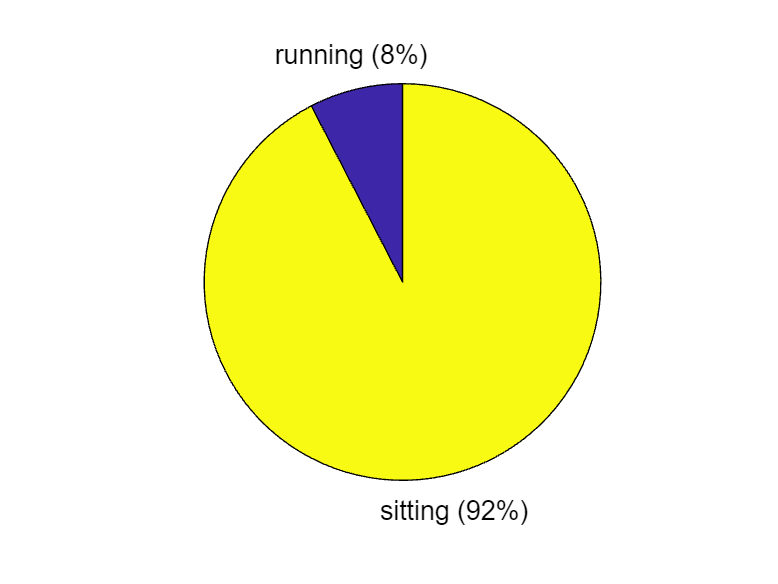

justAcc = timetable2table(unknownAcceleration, "ConvertRowTimes", true); % to be changed
yfit = trainedModel.predictFcn(justAcc);
%{
plot(accelTime,Xacc);
hold on;
plot(accelTime,Yacc); 
plot(accelTime,Zacc);
%xlim([0 50])
legend('X Acceleration','Y Acceleration','Z Aceeleration');
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)');
title('Acceleration Data Vs. Time');
hold off
%}
yfitcat = categorical(cellstr(yfit)); % convert to correct data type for histogram
pie(yfitcat)

## **Compute dist travelled & steps taken using test data**

lat=Position.latitude;
lon=Position.longitude;
positionDatetime=Position.Timestamp;

Xacc = Acceleration.X;
Yacc = Acceleration.Y;
Zacc = Acceleration.Z;
accelDatetime=Acceleration.Timestamp;

% We use the following to obtain linear time data in seconds from a datetime array
positionTime=timeElapsed(positionDatetime);
accelTime=timeElapsed(accelDatetime);

earthCirc = 24901;
totaldis = 0;
%{
for i = 1:(length(lat)-1)
    lat1 = lat(i);     % The first latitude
    lat2 = lat(i+1);   % The second latitude
    lon1 = lon(i);     % The first longitude
    lon2 = lon(i+1);   % The second longitude
    degDis = distance(lat1, lon1, lat2, lon2);
    dis = (degDis/360)*earthCirc;
    
    totaldis = totaldis + dis;
end
%}
totaldis = 0.4093; %to be changed later

stride = 2.5;                   % Average stride (ft)
totaldis_ft = totaldis*5280;    % Converting distance from miles to feet
steps = totaldis_ft/stride;

disp(['The total distance traveled is: ', num2str(totaldis),' miles'])

The total distance traveled is: 0.4093 miles


disp(['You took ', num2str(steps) ' steps'])

You took 864.4416 steps


## **Plotting of acceleration-time graph**

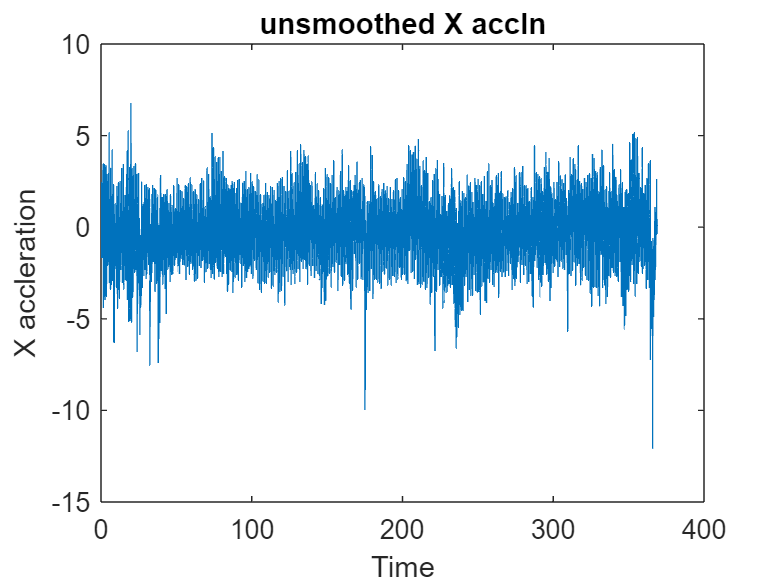

% to split rows into the 3 categories: 
combined = [justAcc table(yfit)];
combined.yfit = categorical(cellstr(combined.yfit));
run_idx = combined.yfit == 'running';
walk_idx = combined.yfit == 'walking';
sit_idx = combined.yfit == 'sitting';

% to add absolute acceleration column:
X = combined.X;
Y = combined.Y;
Z = combined.Z;
combined.abs = sqrt(X.^2+Y.^2+Z.^2);

% to plot graph of abs acceleration against time elapsed:
combined.Timestamp=timeElapsed(combined.Timestamp);
xValues = combined.Timestamp;
yValues = combined.X;
plot(xValues,yValues)
title("unsmoothed X accln")
xlabel("Time")
ylabel("X accleration")

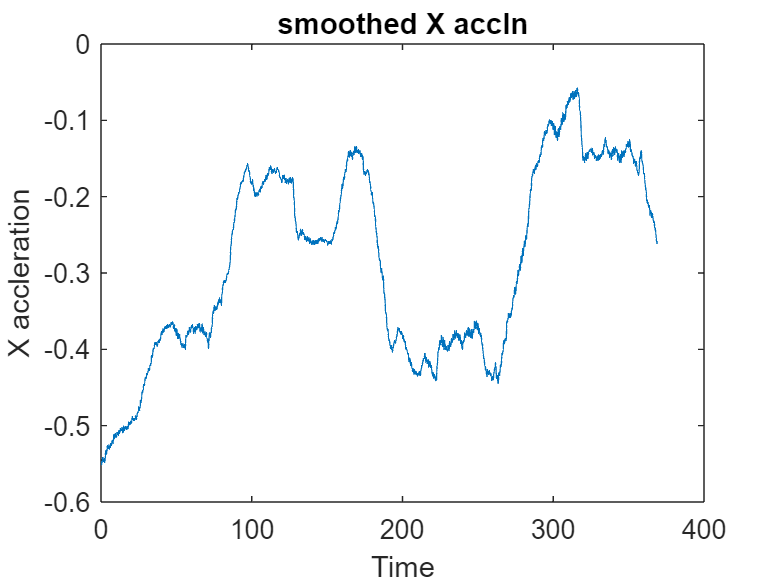


% smoothing of data and re-plotting using smoothed data:
numData = combined(:,{'X','Y','Z','abs'});
smData = smoothdata(numData,"movmean",5000);
xValues = combined.Timestamp;
yValues = smData.X;
plot(xValues,yValues)
title("smoothed X accln")
xlabel("Time")
ylabel("X accleration")

**Calorie Burn**

velocity = (combined.X(1:end-1,:).*(seconds(diff(accelDatetime))))

velocity =     0.0359
    0.0104
   -0.0108
   -0.0141
   -0.0036
   -0.0018
    0.0048
    0.0058
   -0.0000
   -0.0040


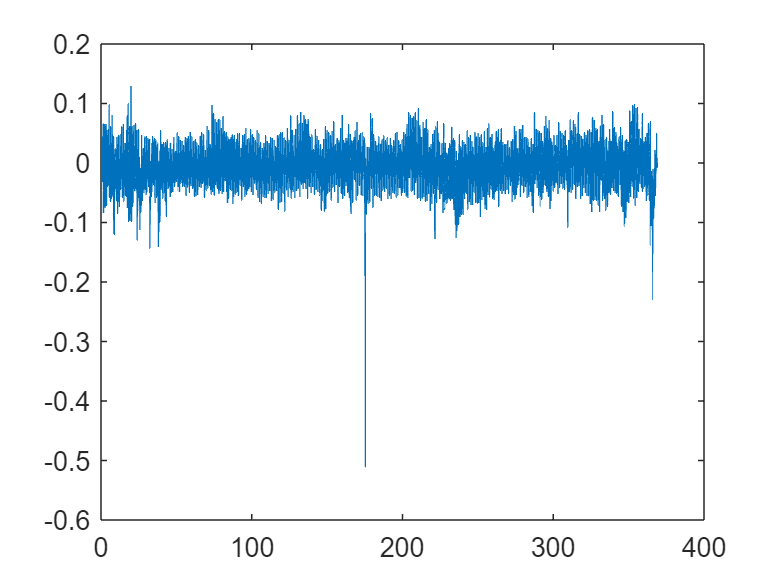

plot (accelTime(2:end,:), velocity)

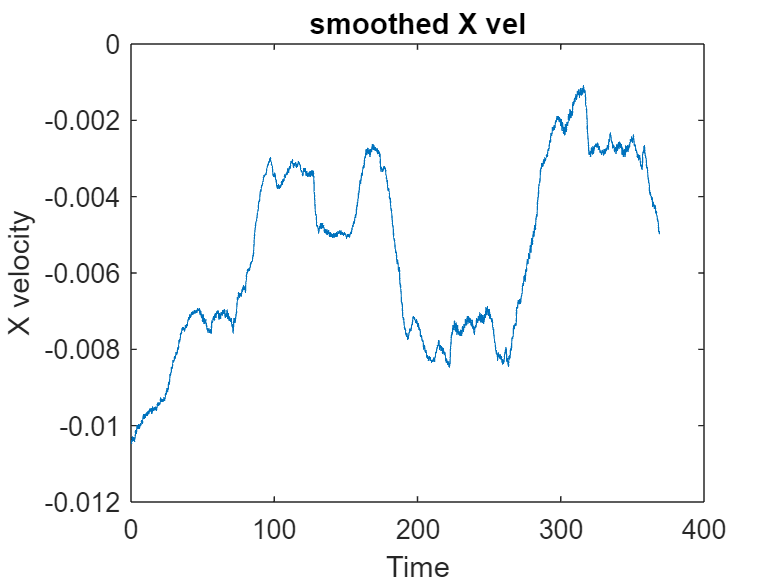


% smoothing of data and re-plotting using smoothed data:
smVelData = smoothdata(velocity,"movmean",5000);
plot(accelTime(2:end,:),smVelData)
title("smoothed X vel")
xlabel("Time")
ylabel("X velocity")


distance = round(totaldis*1609.34,1)

distance = 658.7000

time = round(accelTime(end)-accelTime(1),1)

time = 369

averageSpeed = round(distance / time,1) % Calculate average speed (m/s)

averageSpeed = 1.8000

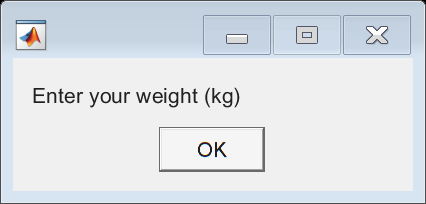

% Estimate intensity based on speed
if averageSpeed < 1.4
    MET = 2.0; % Sedentary/light activity
elseif averageSpeed >= 1.4 & averageSpeed < 1.9
    MET = 3.0;
elseif averageSpeed >= 1.9 & averageSpeed < 3.7
    MET = 5.0; % Jogging
else
    MET = 7.0; % Running
end
duration_hours = time/3600;
msgbox("Enter your weight (kg)")

weight = 70

weight = 70

calorieBurn = MET * weight * duration_hours % Calculate calorie burn

calorieBurn = 21.5250

**Position Map**

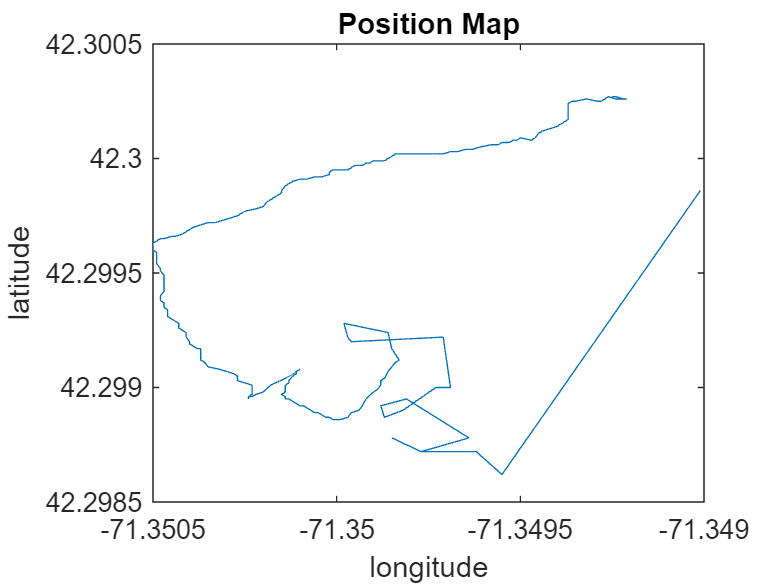

plot(Position.longitude,Position.latitude)
ylabel("latitude")
xlabel("longitude")
title("Position Map")